# A Molecular Model for Intercellular Synchronization in the Mammalian Circadian Clock

## Init params

N = 100; % must be a square number
is_LD = false;

% disturb_v = 0.1;
% disturb_k = 0.2;
disturb_v = 0.1;
disturb_k = 0.2;

p_0 = init_pre_params();
v_sP0 = init_v_sP0(N, disturb_v);
p = init_params(N, disturb_k);

alpha = spatial_weight(N);
epsilon = calculate_eps(alpha);

y = init_y(N);

num_eq = 17;
num_param = 56;

## Options

tspan = [0 480];
options = odeset('RelTol',1e-8,'AbsTol',1e-10);

## Simulate DD

ode_DD = @(t, y) LG_VIP_total(t, y, p_0, p, N, epsilon, alpha, v_sP0, is_LD);

[t1, y1] = ode45(ode_DD, tspan, y, options);

## Visualize DD

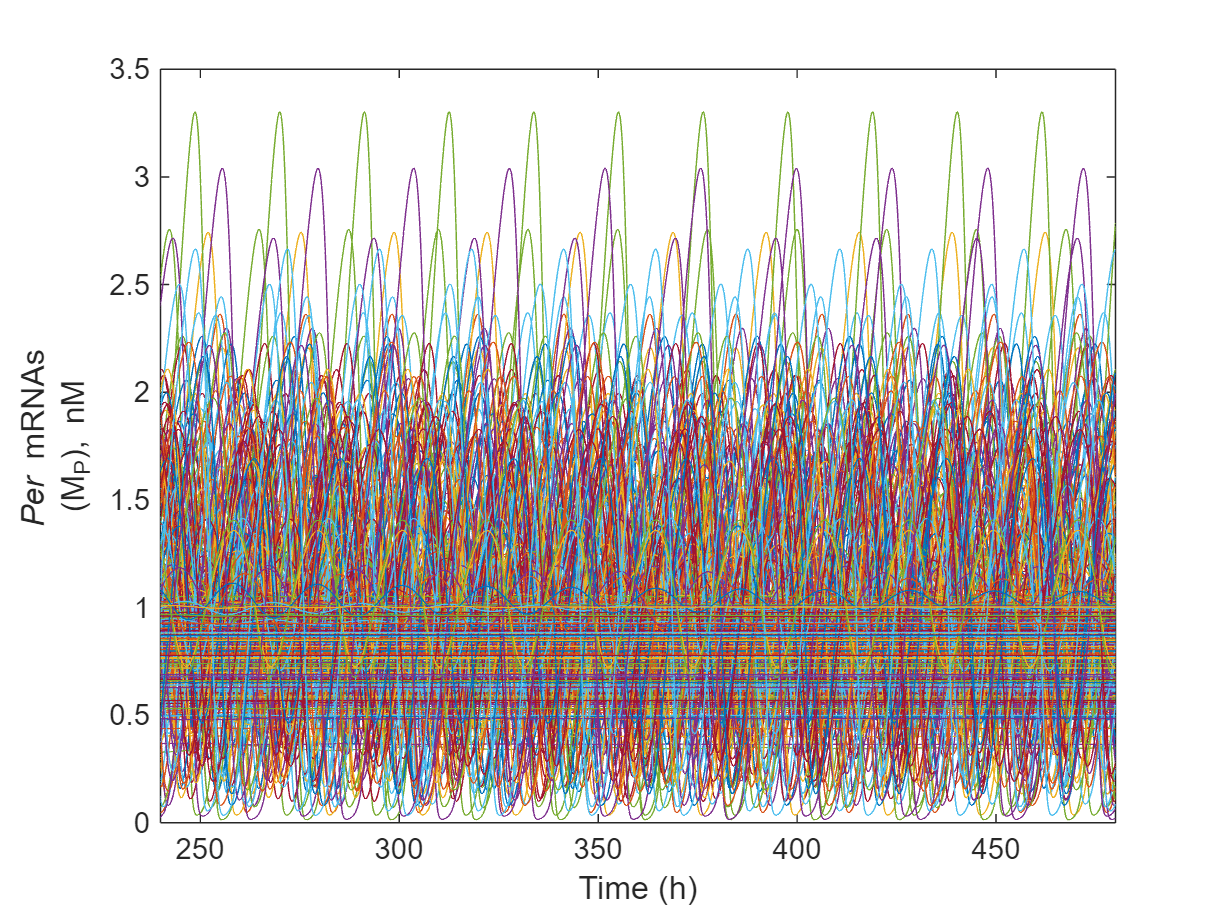

delay = 240;
M_P = y1(:, 1:num_eq:end);

figure;
plot(t1, M_P);
xlim([t1(end)-delay, t1(end)]);
xlabel('Time (h)');
ylabel({'{\it Per} mRNAs', '(M_P), nM'});

## Simulate LD

is_LD = true;
ode_LD = @(t, y) LG_VIP_total(t, y, p_0, p, N, epsilon, alpha, v_sP0, is_LD);

[t2, y2] = ode45(ode_LD, tspan, y, options);

## Visualize LD

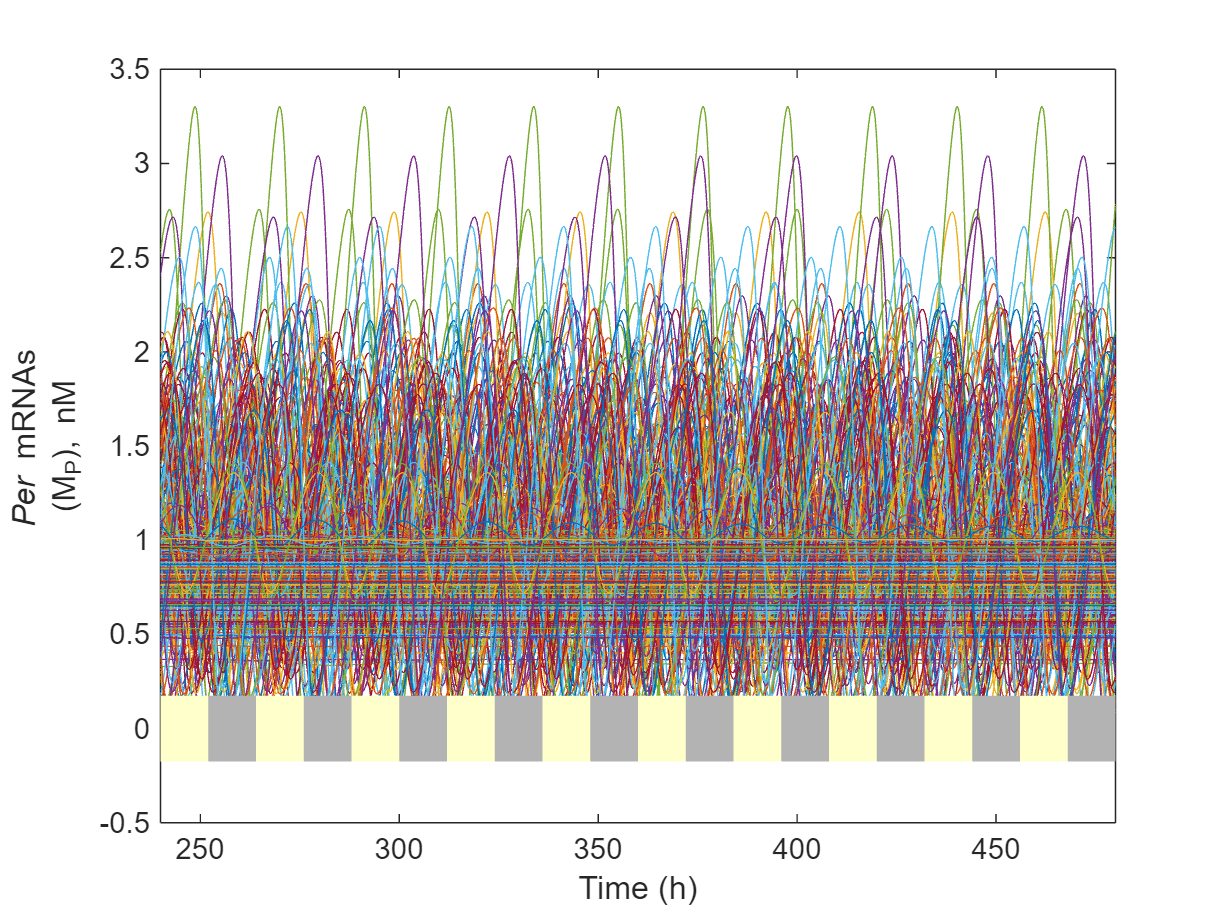

M_P = y2(:, 1:num_eq:end);

figure;
plot(t2, M_P);
xlim([t2(end)-delay, t2(end)]);
xlabel('Time (h)');
ylabel({'{\it Per} mRNAs', '(M_P), nM'});

% Get current axis limits
ax = gca;
ylims = ylim;
ypos = ylims(1) - 0.05*(ylims(2)-ylims(1)); % Position slightly below the plot

% Add light-dark indicators
start_time = t2(end) - delay;
end_time = t2(end);
for t = ceil(start_time/24)*24:24:end_time
    % Light phase (white or light yellow rectangle)
    rectangle('Position', [t, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [1 1 0.8], 'EdgeColor', 'none');
    % Dark phase (gray rectangle)
    rectangle('Position', [t+12, ypos, 12, 0.1*(ylims(2)-ylims(1))], ...
              'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none');
end